# Model 1: (Age) Polynomial based model

% K = # of clusters
% T = # of cycles/ time points
% N = # of units
% P = # of features
% X = (P x T) feature matrix
% Q = (P x K) latent clusters
% C = (K x N) membership vectors
% Y = (T x N) status measurement/ health condition
% W = (N x N) similarity matrix/ regularization matrix
K = 3; % K = 5;
T = 30000;
N = 100;
P = 3;

## Simulate C

% sigmaK = variance for each multivariate normal distribution
sigK=1000;
for i=1:K
  s=1*ones(K,1);
  s(i)=s(i)+sigK;
  sigmaK{i}=spdiags(s,0,K,K);
end

% generate C_i
p=[0.4 0.3 0.3]; % probability distribution for each class
% p=[0.2,0.2,0.2,0.2,0.2]; % for the case K = 5
for i=1:N
    class(i)=discreteinvrnd(p,1,1);
    if(size(sigmaK{class(i)},1)~=K)
        error('check the dimension of each sigma')
    else
        C_1(:,i)=abs(mvnrnd(zeros(K,1),sigmaK{class(i)}));
        C_1(:,i)=C_1(:,i)./sum(C_1(:,i));
    end
end

## Simulate Q

Q_1=[14,3,-0.1;7,0.6,-0.001;6.5,0.06,-0.0005]'; %K = 3
% Q_1=[10,3,-0.01;10,1,-0.2;7,0.8,-0.5;2,0.5,-0.5;2,-0.1,-0.01]'; %K = 5

## Simulate W

W = normc(C_1)'*normc(C_1);

## Simulate X

x_t = 0.001:0.001:30;
x_t2 = x_t.^2; 
for i=1:N
  X_1{i}=[ones(1,T); x_t; x_t2];
end

## Simulate Y

if(length(X_1)~=N || size(Q_1,2)~=K)
    error('check the size of INPUT');
end
Y_1=[];
for i=1:N
    ni=size(X_1{i},2);
    e=normrnd(0,0.1,ni,1);
    Y_1=[Y;C_1(:,i)'*Q_1'*X_1{i}+e'];
end

## Plot Y

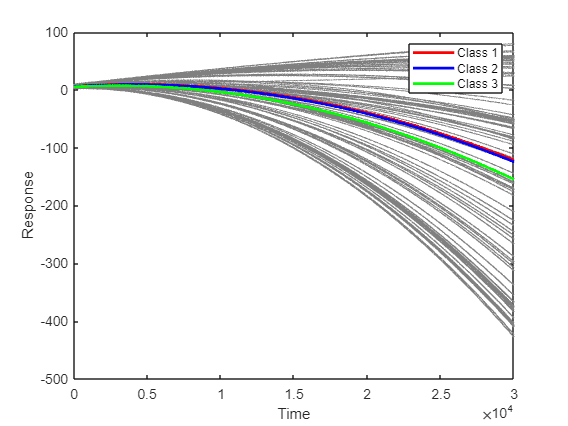

figure;
plot(Y_1','Color',[0.5,0.5,0.5]);
hold on;
h1=plot([1:T],mean(Y_1(class==1,:)),'r',[1:T],mean(Y_1(class==2,:)),'b',[1:T],mean(Y_1(class==3,:)),'g','LineWidth',2);
xlabel('Time','LineWidth',2);
ylabel('Response','LineWidth',2);
legend(h1,'Class 1','Class 2','Class 3');